# Example for using detectBlink function

detectBlink is a function that could find blink locations in an one to three channels EEG signal collect from Fp1, Fp2 and Fz electrodes.

## Syntax

locations = detectBlinks(signals,samplingRate)

locations = detectBlinks(signals,samplingRate,options)

locations = detectBlinks(signals,samplingRate,outputOptions)

## Prepare data

The input signal could be matix or table. detectBlink function can work with 1 to 3 channel input.

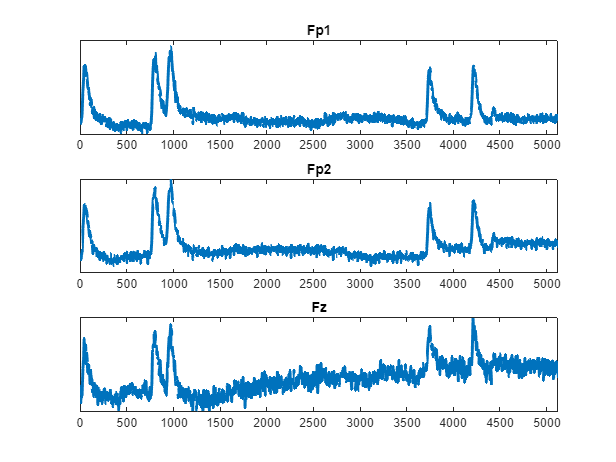

Ds = load("Package\sampleData.mat").Ds;
samplingRate = 512;
signalMultiple = Ds{1,1}{1,1};
signalSingle = signalMultiple.Fp1;
figure;
l = {'Fp1','Fp2','Fz'};
hold("on");
data = signalMultiple.Variables;
for i=1:3
    subplot(3,1,i);
    plot(data(:,i), LineWidth=2);
    xlim([0, 5120]);    
    yticks([]);  
    title([l{i}]);
end
hold("off");

## Detet the blinks in provided signal

Input signal and sampling rate of the signal (seccond).  The signal should shape as:

tableSignal = signalMultiple(1:10,:), type = class(signalMultiple)

tableSignal = 10×3 table
     Fp1       Fp2        Fz   
    ______    ______    _______

    -18559    -10134    -7235.3
    -18559    -10130    -7239.5
    -18550    -10135      -7242
    -18549    -10142    -7242.2
    -18550    -10141    -7239.2
    -18550    -10140    -7238.9
    -18552    -10140    -7240.9
    -18550    -10138    -7241.1
    -18548    -10138      -7241
    -18545    -10139    -7238.4


type = 'table'

Also matrix is ok, and for a normal signal, the shape of channels by time or time by channels are both avaliable.

matrixSignal = signalMultiple(1:10,:).Variables, type = class(matrixSignal)

matrixSignal = 1.0e+04 *

   -1.8559   -1.0134   -0.7235
   -1.8559   -1.0130   -0.7240
   -1.8550   -1.0135   -0.7242
   -1.8549   -1.0142   -0.7242
   -1.8550   -1.0141   -0.7239
   -1.8550   -1.0140   -0.7239
   -1.8552   -1.0140   -0.7241
   -1.8550   -1.0138   -0.7241
   -1.8548   -1.0138   -0.7241
   -1.8545   -1.0139   -0.7238


type = 'double'

matrixSignal = matrixSignal'

matrixSignal = 1.0e+04 *

   -1.8559   -1.8559   -1.8550   -1.8549   -1.8550   -1.8550   -1.8552   -1.8550   -1.8548   -1.8545
   -1.0134   -1.0130   -1.0135   -1.0142   -1.0141   -1.0140   -1.0140   -1.0138   -1.0138   -1.0139
   -0.7235   -0.7240   -0.7242   -0.7242   -0.7239   -0.7239   -0.7241   -0.7241   -0.7241   -0.7238


The default output is a list of indexs of the blinks in signal.

locations = detectBlinks(signalMultiple,samplingRate)

locations =         3756        4232        5688        8620       10104       10392       11468       14172       18028       19256       21784       26520       27124       28236       33144       36588       39700       41484       41696       45236       45784       46652       46668       47132       47492       48716       55568       59124       62784       65068       74400       75068       75584       77320       77624       79236       82072       83088       86372       86660       89908       91380       91856       92156       94588


Plot the Fp1 signal and point out the blink locations.

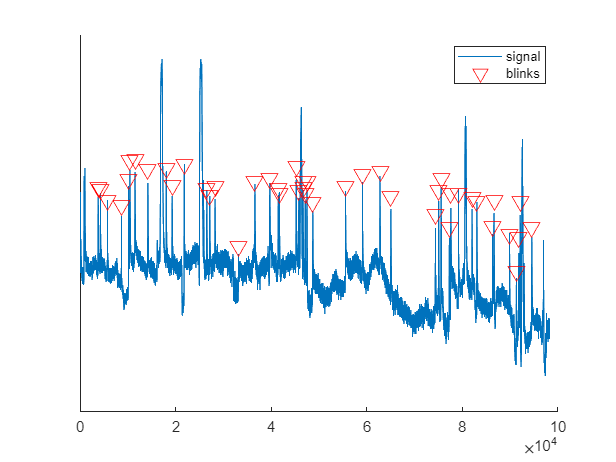

coordinate = signalSingle(locations);
figure;
hold('on');
plot(signalSingle,'Color',[0,0.4470,0.7410]);
plot(locations,coordinate+50,'rv','MarkerSize',10);
legend(["signal","blinks"])
hold('off');
yticks([]);

## Optional inputs

### Mode name

The default model is 'TCNOC', exept this, '1d-CNN', 'LSTM', 'biLSTM', 'TCN', 'WT-CNN', '1d-CNNOC', 'LSTMOC', 'biLSTMOC' and 'WT-CNNOC' are also avaliable. For example:

locations = detectBlinks(signalMultiple,samplingRate,'1d-CNN')

locations =         3756        4232        5688        8620       10104       10392       11464       14172       18024       19256       21784       25856       26516       27124       28236       36588       39704       41488       41700       45236       45780       46672       47132       47488       48716       55568       59124       62784       65068       74400       75068       75584       77320       77628       79236       82072       83088       86368       86660       89908       91380       91856       92156       92968       94588


### Shift factor

Inside the prdiction pipline, there are multiple predictors working on shifted signals. The number of it is pow2(shiftFactor). Increase this may increase accuracy but cost more time accordingly. The default factor is 3, uses 8 predictors.

timeWithFactor1 = detectBlinks(signalMultiple,samplingRate,shiftFactor=1,output={'time'})

timeWithFactor1 = 11.7130

timeWithFactor5 = detectBlinks(signalMultiple,samplingRate,shiftFactor=5,output={'time'})

timeWithFactor5 = 49.5216

### Plot 

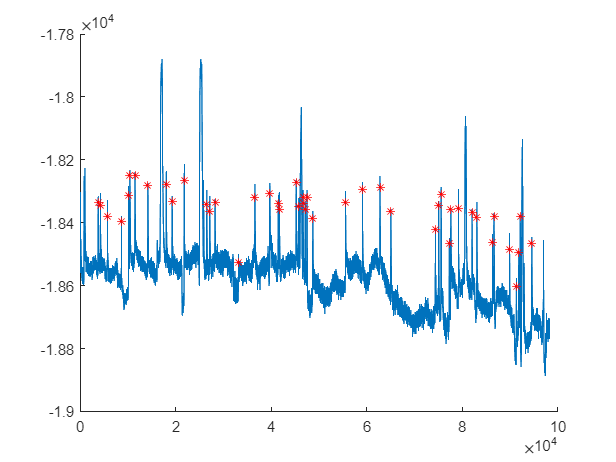

detectBlinks(signalMultiple,samplingRate,plot=true);

## Optional outputs

The location index list is the default out put. Other two are time (runtime) and mask (model predicted label for every time step)

[labels,runtime] = detectBlinks(signalMultiple,samplingRate,output={'mask','time'}); 
labels(1000:1010),runtime

ans = 1×11 categorical array
     n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a 


runtime = 17.4001